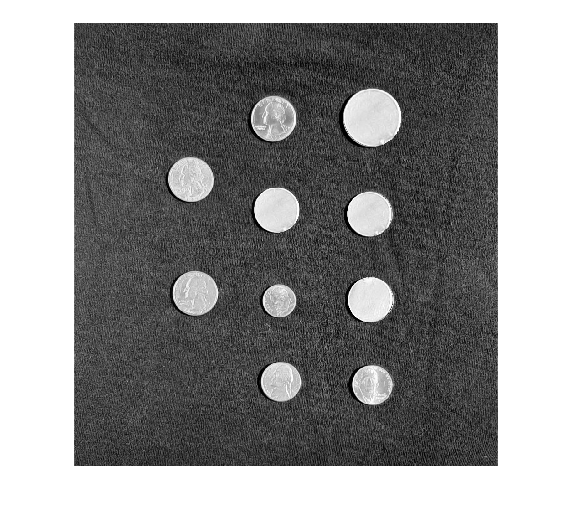

testImageIdx = randi([1,3]);
testCoinImage = imread("testCoinImage"+testImageIdx+".png");
figure, imshow(testCoinImage)

[testCoinMask, maskedTestCoinImage] = segmentImage(testCoinImage);

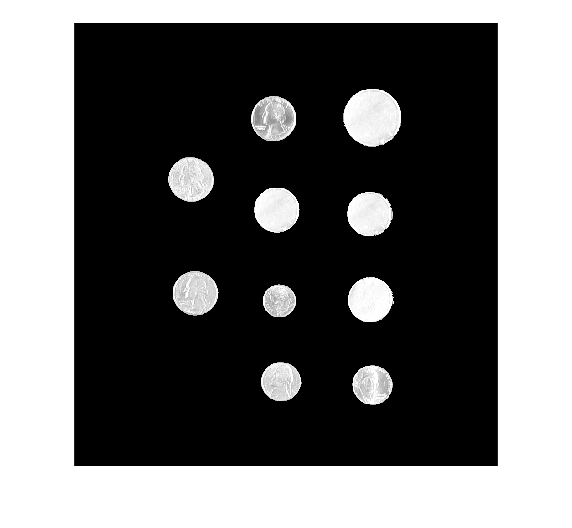

imshow(maskedTestCoinImage)

faceEdge = edge(maskedTestCoinImage,"roberts")

faceEdge = 972×930 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

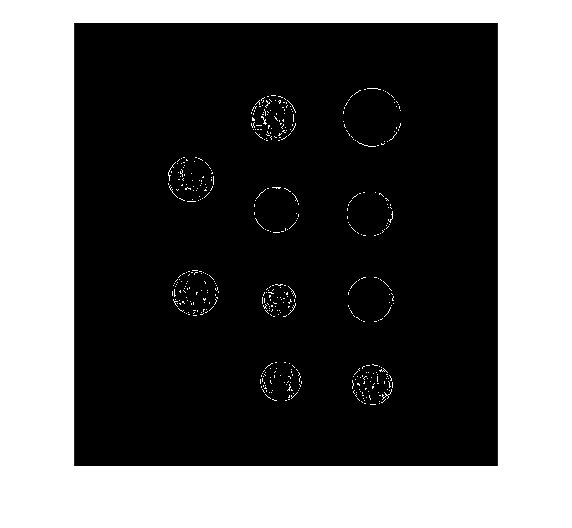

imshow(faceEdge)

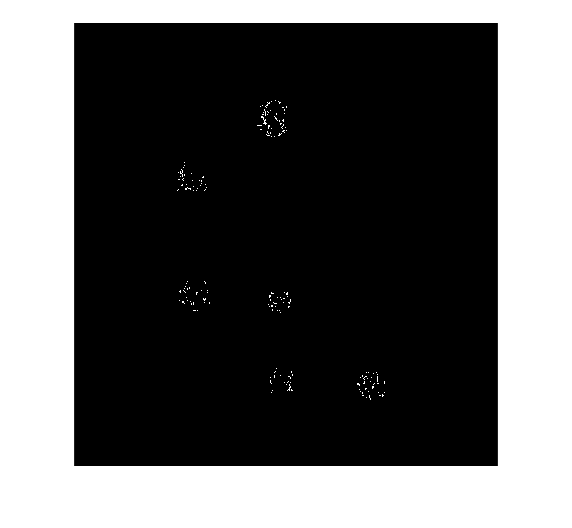

% Erode the testCoinMask to shrink the coins' boundaries.
se = strel('disk', 10); % You might need to adjust the disk radius depending on the coin size in your image.
erodedMask = imerode(testCoinMask, se);

% Logically combine the eroded mask with the faceEdge to retain only the desired edges.
faceEdgeMask = faceEdge & erodedMask;

figure, imshow(faceEdgeMask);

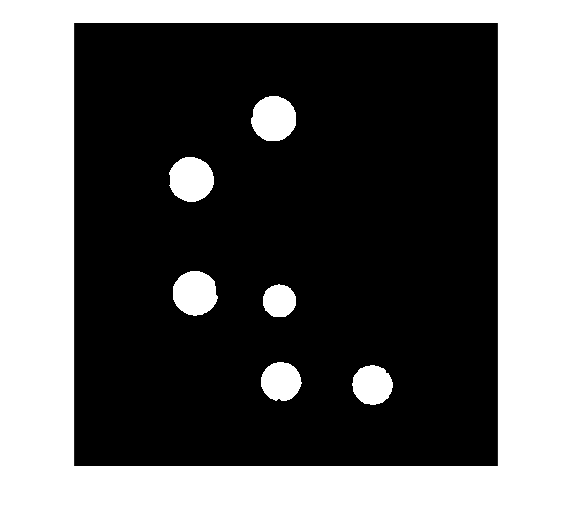

% Dilate the faceEdgeMask to expand the interior details to the size of valid coins.
% The radius of dilation should be chosen such that it's large enough to cover a valid coin, but not overlap with blank coins.
seDilate = strel('disk', 20); % Adjust the disk radius based on your observations.
dilatedFaceEdgeMask = imdilate(faceEdgeMask, seDilate);

% Logically combine (AND operation) the dilated faceEdgeMask with the testCoinMask to obtain only the valid coins.
validCoinMask = dilatedFaceEdgeMask & testCoinMask;

figure, imshow(validCoinMask);

% Label connected components in validCoinMask
labeledMask = bwlabel(validCoinMask);

% Measure the area of each component
stats = regionprops(labeledMask, 'Area')

stats = 6×1 struct array with fields:
    Area



% Extract the area values from the stats structure
areas = [stats.Area];

% Define a threshold for minimum area; this might need adjustment
areaThreshold = 2000;  % Adjust this based on the approximate smallest area of a valid coin

% Find labeled regions that meet the area criteria
validRegions = find(areas > areaThreshold);

% Create a refined mask
ValidCoinMask = ismember(labeledMask, validRegions);

figure, imshow(ValidCoinMask);

function [BW,maskedImage] = segmentImage(X)
%segmentImage Segment image using auto-generated code from Image Segmenter app
%  [BW,MASKEDIMAGE] = segmentImage(X) segments image X using auto-generated
%  code from the Image Segmenter app. The final segmentation is returned in
%  BW, and a masked image is returned in MASKEDIMAGE.

% Auto-generated by imageSegmenter app on 11-Oct-2023
%----------------------------------------------------


% Adjust data to span data range.
X = imadjust(X);

% Threshold image - global threshold
BW = imbinarize(im2gray(X));

% Open mask with default
radius = 2;
decomposition = 0;
se = strel('disk', radius, decomposition);
BW = imopen(BW, se);

% Close mask with default
radius = 2;
decomposition = 0;
se = strel('disk', radius, decomposition);
BW = imclose(BW, se);

% Fill holes
BW = imfill(BW, 'holes');

% Create masked image.
maskedImage = X;
maskedImage(~BW) = 0;
end
